% Test of LBGAlgorithm
% INPUTS FOR FUNCTION - Number of centroids; dimension; eplison; frames
% Ideas to test for initial centroids -
% 1. y = x
numCentroids = 15; % for test defining number of centroids
randomPoints = randi([0 10],2,100) % random data set

randomPoints =      5     9     4     0     2     6     3     8     0     7     4     2     3     3     9    10     0     8     5     9     3     2     7     6    10     3    10     9     5     2     5     3     5     8     7     0     3    10     8     6    10     8     0     7     4     9     4     9     7     7
     5     3    10    10     7     7     6     0    10     2     1     2     1     1     1     4     3     8     7     0     0     7     9     0     8     5     7     4     6     8     7     1     3     8     1     6    10     3     9     9     6     6     4     5    10     9     6    10     2     0


scatter(randomPoints(1,:),randomPoints(2,:),'b','o') % plotting random points
hold on
randomXY = randomPoints' % putting random points in [X Y] format

randomXY =      5     5
     9     3
     4    10
     0    10
     2     7
     6     7
     3     6
     8     0
     0    10
     7     2


lengthsplitup = ceil(100/numCentroids); % how to evenly split input data;frames/numC
startCentroids = zeros(numCentroids,2); % zeros(numCentroids,dimensions)
j = 0;
% for loop to give us all the initial centroids we need
% for i = 1:numCentroids
%     if i == 1
%         startCentroids(i,:) = mean(randomXY(i:lengthsplitup,:));
%     elseif i ~= numCentroids
%         startCentroids(i,:) = mean(randomXY(j:j+lengthsplitup-1,:));
%     else
%         startCentroids(i,:) = mean(randomXY(j:end,:));
%     end
%     j = i + lengthsplitup; % iterating j to make sure we mean all data with no repeats
% end
please = mean(randomXY);
please1 = mean(randomXY);
killme = (max(randomXY)-min(randomXY))/numCentroids;
iter = min(randomXY)

iter =      0     0


killme1 = (max(please1)-min(please1))/numCentroids;
iter1 = min(please1)

iter1 = 5.2300

for i = 1:numCentroids
    startCentroids(i,:) = iter;
    iter = iter + killme;
%     if mod(i,2) == 0
%         startCentroids(i,:) = killme + iter;
%         iter = iter + killme;
%     else
%         startCentroids(i,:) = killme1 - iter1;
%         iter1 = iter1 - killme1;
%     end
end
startCentroids % displaying initial centroid values for testing purposes

startCentroids =          0         0
    0.6667    0.6667
    1.3333    1.3333
    2.0000    2.0000
    2.6667    2.6667
    3.3333    3.3333
    4.0000    4.0000
    4.6667    4.6667
    5.3333    5.3333
    6.0000    6.0000


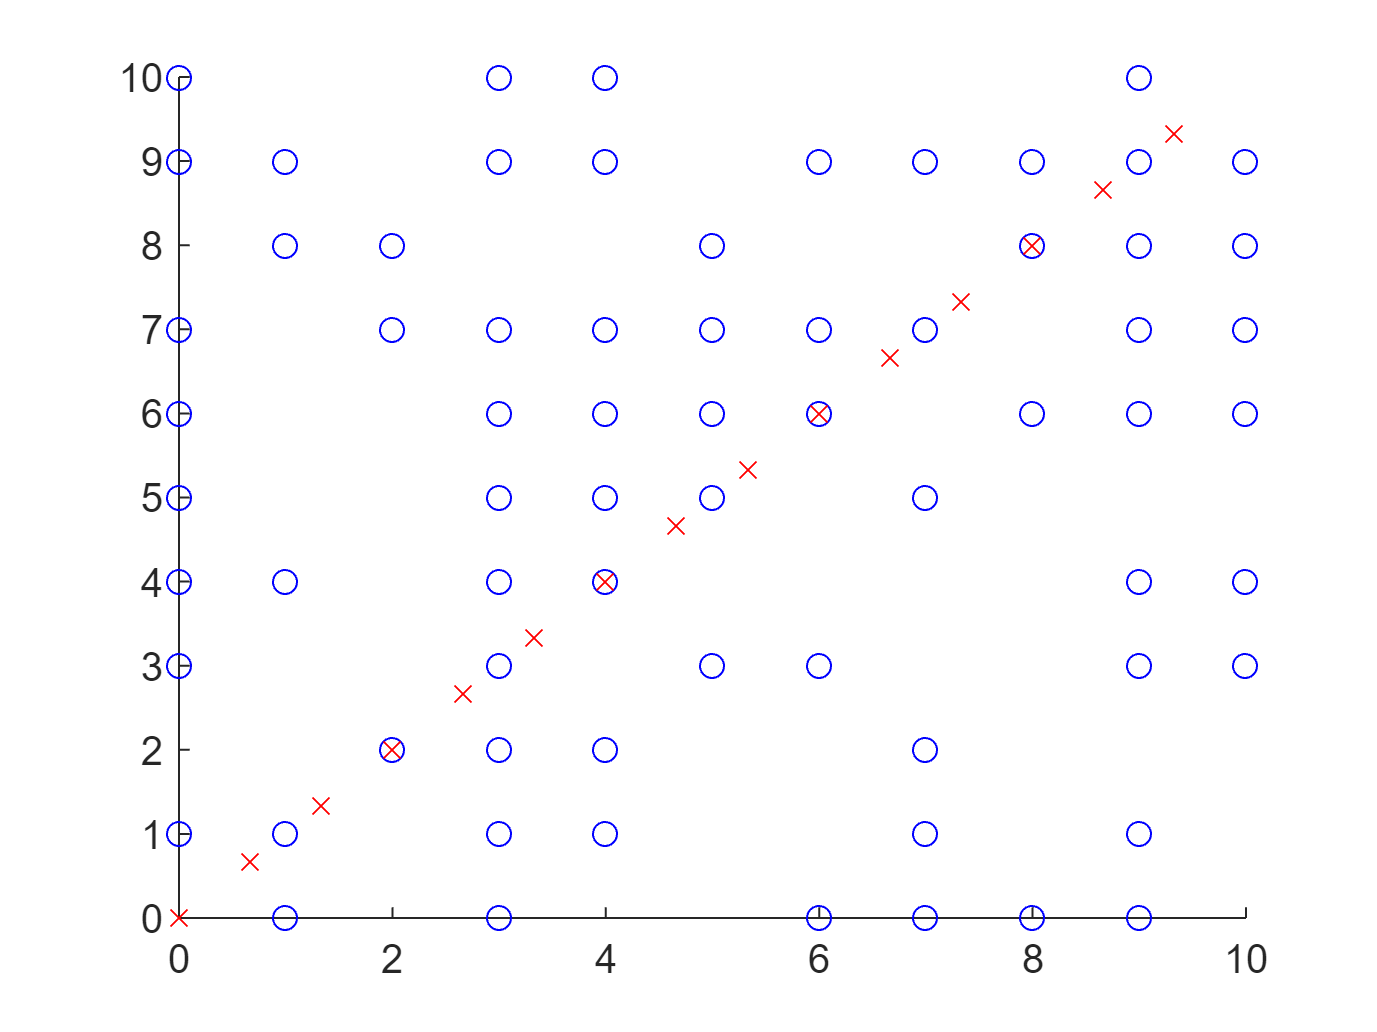

% end of getting all the centroids we need to start
scatter(startCentroids(:,1),startCentroids(:,2),'r','x') % plotting initial centroid
hold off

eplison = 0.001; % defining eplison value
Dp = 100000000; % initializing previous distortion as a large number
while (1)
    values = disteu(randomPoints,(startCentroids)') % getting distances
    [rows,cols] = size(values); % used to determine size for groups matrix
    groups = zeros(rows,cols); % defining groups matrix (frames,numC)
    % for loop for grouping
    for i = 1:rows
        holder = min(values(i,:));
        for j = 1:cols
            if values(i,j) == holder
                groups(i,j) = holder;
            end
        end
    end
    % end of for loop for grouping
    groups % displaying groups; some centroids may not have any points
    Do = zeros(1,cols); % making distortion matrix (1,numCentroids)
    % for loop for summing minimum distances
    for i = 1:cols
        Do(1,i) = sum(groups(:,i)); % summing each column at a time; 1/(frames)
    end
    % end of for loop for summing minimum distances
    Do = (1/100)*sum(Do) % summing final rows of each group; this makes Do one value
    stuff = (Dp - Do)/(Do); % distortion comparison equation
    % if else to decide if another loop needs to be done
    if stuff < eplison
        break;
    else
        Dp = Do;
    end
    % end of if else to decide if another loop needs to be done
    % if another loop needs to be done recalculate centroids
    [r,c] = size(groups); % used for loops below
    holderC = zeros(1,2); % (1,dimensions)
    for i = 1:c
        for j = 1:r
            if groups(j,i) == 0 % in case the centroid is on a point
                % checking to see if centroid is on a point
                hatethis = randomXY(j,:);
                if startCentroids(i,:) == hatethis % only entered if centroid is on data point
                    holderC = [holderC; hatethis];
                end
            else % this if statement gets the original data values
                hatethis = randomXY(j,:);
                holderC = [holderC; hatethis];
            end
        end
        holderC = holderC(2:end,:) % getting rid of the initial 0 0 when holderC was defined
        if isempty(holderC) % just in case a centroid has no data points then do not update the centroid
            startCentroids(i,:) = startCentroids(i,:); % keeps previous centroid the same
        else
            [lastr,lastc] = size(holderC);
            newC = zeros(1,lastc); % (1,dimensions)
            for k = 1:lastc % calculates new centroids; works by doing each column so X then Y then etc
                newC(1,k) = mean(holderC(:,k)); % sum / number of points in that group
            end
            startCentroids(i,:) = newC; % storing new centroid in place of old one
            holderC = zeros(1,2); % resetting
        end
    end
    startCentroids % seeing new centroid values
    % end of recalculating centroids for next loop
end

values =     7.0711    6.1283    5.1854    4.2426    3.2998    2.3570    1.4142    0.4714    0.4714    1.4142    2.3570    3.2998    4.2426    5.1854    6.1283
    9.4868    8.6538    7.8457    7.0711    6.3421    5.6765    5.0990    4.6428    4.3461    4.2426    4.3461    4.6428    5.0990    5.6765    6.3421
   10.7703    9.9107    9.0676    8.2462    7.4536    6.6999    6.0000    5.3748    4.8534    4.4721    4.2687    4.2687    4.4721    4.8534    5.3748
   10.0000    9.3571    8.7686    8.2462    7.8031    7.4536    7.2111    7.0868    7.0868    7.2111    7.4536    7.8031    8.2462    8.7686    9.3571
    7.2801    6.4722    5.7057    5.0000    4.3843    3.9016    3.6056    3.5434    3.7268    4.1231    4.6786    5.3437    6.0828    6.8718    7.6956
    9.2195    8.2798    7.3409    6.4031    5.4671    4.5338    3.6056    2.6874    1.7951    1.0000    0.7454    1.3744    2.2361    3.1447    4.0689
    6.7082    5.8214    4.9554    4.1231    3.3500    2.6874    2.2361    2.1344    2

groups =          0         0         0         0         0         0         0         0    0.4714         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    4.2426         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    4.2687    4.2687         0         0         0
         0         0         0         0         0         0         0    7.0868    7.0868         0         0         0         0         0         0
         0         0         0         0         0         0         0    3.5434         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    0.7454         0         0         0         0
         0         0         0         0         0         0         0    2.1344     

Do = 3.0332


holderC =

  0×2 empty double matrix



holderC =      0     1


holderC =      0     3
     3     0
     1     1


holderC =      2     2
     3     1
     3     1
     3     1
     0     4
     0     4
     2     2


holderC =      4     1
     6     0
     0     6
     1     4
     3     2
     0     5


holderC =      6     0
     0     6
     7     0
     4     2
     0     7
     3     4
     3     3


holderC =      8     0
     3     5
     5     3
     7     1
     4     4
     4     4
     5     3


holderC =      0    10
     2     7
     3     6
     0    10
     7     2
     9     1
     9     0
     2     7
     2     8
     7     2


holderC =      5     5
     0    10
     0    10
     9     1
     5     6
     2     8
     4     6
     4     7
     2     8
     1     9


holderC =      9     3
     5     7
     5     7
     7     5
     6     6
     9     3
     3     9
     5     7
     5     7
     6     6


holderC =      4    10
     6     7
    10     4
     9     4
     3    10
    10     3
     8     6
     4    10
     5     8
     4    10


holderC =      4    10
    10     4
     6     9
     4    10
     4    10
     9     6
     6     9
     6     9
     9     6


holderC =      8     8
     7     9
     8     8
    10     6
     9     7
    10     6
    10     6


holderC =     10     7
     8     9
     9     8
    10     7


holderC =     10     8
     9     9
     9    10
    10     8
    10     9
     9    10
     9    10


startCentroids =          0         0
         0    1.0000
    1.3333    1.3333
    1.8571    2.1429
    2.3333    3.0000
    3.2857    3.1429
    5.1429    2.8571
    3.4444    5.9444
    3.1818    7.0000
    5.9091    6.0909


values =     7.0711    6.4031    5.1854    4.2474    3.3333    2.5274    2.1476    1.8198    2.7029    1.4200    2.4328    3.4301    4.4124    5.0621    6.0643
    9.4868    9.2195    7.8457    7.1941    6.6667    5.7161    3.8598    6.2876    7.0605    4.3712    4.5580    5.7144    4.1453    4.7566    6.1578
   10.7703    9.8489    9.0676    8.1441    7.1957    6.8942    7.2337    4.0934    3.1096    4.3504    4.0608    3.0892    5.6352    5.7118    5.4958
   10.0000    9.0000    8.7686    8.0736    7.3786    7.6037    8.8017    5.3209    4.3731    7.0851    7.2843    6.7156    9.3066    9.5197    9.4675
    7.2801    6.3246    5.7057    4.8592    4.0139    4.0658    5.2001    1.7890    1.1818    4.0134    4.5737    4.5812    6.8586    7.2887    7.7315
    9.2195    8.4853    7.3409    6.3840    5.4263    4.7164    4.2306    2.7650    2.8182    0.9136    0.5890    1.1967    2.8607    3.3354    4.0431
    6.7082    5.8310    4.9554    4.0229    3.0732    2.8714    3.8039    0.4479    1

groups =          0         0         0         0         0         0         0         0         0    1.4200         0         0         0         0         0
         0         0         0         0         0         0    3.8598         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0    3.0892         0         0         0
         0         0         0         0         0         0         0         0    4.3731         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.1818         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    0.5890         0         0         0         0
         0         0         0         0         0         0         0    0.4479     

Do = 1.7033

holderC =      1     0


holderC =      0     3
     0     1


holderC =      3     0
     1     1


holderC =      2     2
     3     1
     3     1
     3     1
     3     2
     2     2


holderC =      0     4
     1     4
     0     5
     0     4


holderC =      4     2
     4     4
     3     4
     4     4
     3     3


holderC =      9     3
     8     0
     7     2
     4     1
     9     1
     9     0
     6     0
     5     3
     7     1
     7     2


holderC =      3     6
     3     5
     4     6
     4     5
     4     5


holderC =      0    10
     2     7
     0    10
     2     7
     2     8
     0     6
     3    10
     4     7
     2     8
     1     9


holderC =      5     5
     5     7
     5     6
     5     7
     7     5
     6     6
     5     7
     5     7
     6     6
     5     7


holderC =      6     7
     7     7


holderC =      4    10
     7     9
     6     9
     4    10
     5     8
     4    10
     6     9
     6     9


holderC =     10     4
     8     8
     9     4
     8     8
    10     3
    10     6
     8     6
     9     4
     9     6
     9     7


holderC =     10     8
    10     7
    10     8
     9     8
    10     7


holderC =      8     9
     9     9
     9    10
    10     9
     9    10
     9    10


startCentroids =     1.0000         0
         0    2.0000
    2.0000    0.5000
    2.6667    1.5000
    0.2500    4.2500
    3.6000    3.4000
    7.0000    1.5714
    3.6000    5.4000
    1.6875    8.1875
    5.4000    6.3000


values =     6.4031    5.8310    5.4083    4.2065    4.8088    2.1260    3.9693    1.4560    4.5970    1.3601    2.5000    4.2573    4.1821    5.4589    6.0208
    8.5440    9.0554    7.4330    6.5085    8.8388    5.4148    2.4578    5.9093    8.9656    4.8836    4.7170    7.2887    2.5754    4.6690    6.5000
   10.4403    8.9443    9.7082    8.6039    6.8648    6.6121    8.9466    4.6174    2.9382    3.9560    3.9051    1.4577    6.7868    6.2769    5.0249
   10.0499    8.0000    9.7082    8.9085    5.7554    7.5180   10.9563    5.8412    2.4765    6.5460    7.1589    5.3033   10.1589   10.0896    9.0139
    7.0711    5.3852    6.5000    5.5403    3.2596    3.9395    7.3803    2.2627    1.2279    3.4713    4.5000    3.9528    7.2843    7.8230    7.4330
    8.6023    7.8102    7.6322    6.4313    6.3738    4.3267    5.5199    2.8844    4.4730    0.9220    0.5000    2.3717    3.4523    3.8471    3.9051
    6.3246    5.0000    5.5902    4.5123    3.2596    2.6683    5.9676    0.8485    2

groups =          0         0         0         0         0         0         0         0         0    1.3601         0         0         0         0         0
         0         0         0         0         0         0    2.4578         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0    1.4577         0         0         0
         0         0         0         0         0         0         0         0    2.4765         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.2279         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0    0.5000         0         0         0         0
         0         0         0         0         0         0         0    0.8485     

Do = 1.1444

holderC =      1     0
     1     1


holderC =      0     3
     0     1


holderC =      3     0


holderC =      4     1
     2     2
     3     1
     3     1
     3     1
     4     2
     3     2
     2     2


holderC =      0     6
     0     4
     1     4
     0     5
     0     4


holderC =      5     3
     4     4
     3     4
     4     4
     3     3
     5     3


holderC =      9     3
     8     0
     7     2
     9     1
     9     0
     6     0
     7     1
     7     2
     7     0
     9     3


holderC =      3     6
     3     5
     4     6
     4     5
     3     7
     4     5


holderC =      0    10
     2     7
     0    10
     2     7
     2     8
     3    10
     2     8
     1     9
     3     9
     0     7


holderC = 11×2
     5     5
     5     7
     5     6
     5     7
     7     5
     4     7
     6     6
     5     7
     5     7
     6     6


holderC = 4×2
     6     7
     8     8
     8     8
     7     7


holderC = 9×2
     4    10
     7     9
     6     9
     4    10
     5     8
     4    10
     4     9
     6     9
     6     9


holderC = 11×2
    10     4
     9     4
    10     3
    10     6
     8     6
     9     4
     9     6
    10     6
    10     6
     9     4


holderC = 6×2
    10     8
    10     7
    10     8
     9     8
     9     7
    10     7


holderC = 8×2
     8     8
     8     8
     8     9
     9     9
     9    10
    10     9
     9    10
     9    10


startCentroids = 15×2
    1.0000    0.5000
         0    2.0000
    3.0000         0
    3.0000    1.5000
    0.2000    4.6000
    4.0000    3.5000
    7.6364    1.3636
    3.5000    5.6667
    1.3333    8.5000
    5.2727    6.3636


values = 100×15
    6.0208    5.8310    5.3852    4.0311    4.8166    1.8028    4.4915    1.6415    5.0690    1.3906    3.3634    4.2237    4.3636    5.2941    5.5748
    8.3815    9.0554    6.7082    6.1847    8.9443    5.0249    2.1301    6.1124    9.4355    5.0206    4.8283    7.3375    2.0328    4.5491    6.1301
    9.9624    8.9443   10.0499    8.5586    6.6030    6.5000    9.3707    4.3621    3.0596    3.8527    4.1003    1.3563    7.3327    6.1936    4.8299
    9.5525    8.0000   10.4403    9.0139    5.4037    7.6322   11.5283    5.5703    2.0069    6.4051    7.6689    5.1700   10.6150    9.9847    8.7936
    6.5765    5.3852    7.0711    5.5902    3.0000    4.0311    7.9710    2.0069    1.6415    3.3340    5.2738    3.8233    7.6304    7.6830    7.0766
    8.2006    7.8102    7.6158    6.2650    6.2769    4.0311    5.8691    2.8333    4.9018    0.9664    1.3463    2.3934    3.9133    3.7006    3.4754
    5.8523    5.0000    6.0000    4.5000    3.1305    2.6926    6.5568    0.60

groups = 100×15
         0         0         0         0         0         0         0         0         0    1.3906         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    2.0328         0         0
         0         0         0         0         0         0         0         0         0         0         0    1.3563         0         0         0
         0         0         0         0         0         0         0         0    2.0069         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.6415         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.9664         0         0         0         0         0
         0         0         0         0         0         0         0    0.60

Do = 1.0634

holderC = 2×2
     1     0
     1     1


holderC = 2×2
     0     3
     0     1


holderC = 1×2
     3     0


holderC = 8×2
     4     1
     2     2
     3     1
     3     1
     3     1
     4     2
     3     2
     2     2


holderC = 5×2
     0     6
     0     4
     1     4
     0     5
     0     4


holderC = 7×2
     5     3
     6     3
     4     4
     3     4
     4     4
     3     3
     5     3


holderC = 8×2
     8     0
     7     2
     9     1
     9     0
     6     0
     7     1
     7     2
     7     0


holderC = 6×2
     3     6
     3     5
     4     6
     4     5
     3     7
     4     5


holderC = 12×2
     0    10
     2     7
     0    10
     2     7
     2     8
     3    10
     2     8
     1     9
     3     9
     0     7


holderC = 12×2
     5     5
     6     7
     5     7
     5     6
     5     7
     7     5
     4     7
     6     6
     5     7
     5     7


holderC = 5×2
     8     8
     7     9
     8     8
     8     6
     7     7


holderC = 8×2
     4    10
     6     9
     4    10
     5     8
     4    10
     4     9
     6     9
     6     9


holderC = 12×2
     9     3
    10     4
     9     4
    10     3
    10     6
     9     3
     9     4
     9     6
    10     6
    10     6


holderC = 6×2
    10     8
    10     7
    10     8
     9     8
     9     7
    10     7


holderC = 6×2
     8     9
     9     9
     9    10
    10     9
     9    10
     9    10


startCentroids = 15×2
    1.0000    0.5000
         0    2.0000
    3.0000         0
    3.0000    1.5000
    0.2000    4.6000
    4.2857    3.4286
    7.5000    0.7500
    3.5000    5.6667
    1.3333    8.5000
    5.3333    6.4167


values = 100×15
    6.0208    5.8310    5.3852    4.0311    4.8166    1.7261    4.9308    1.6415    5.0690    1.4554    3.6770    4.2518    4.4363    5.2941    6.0208
    8.3815    9.0554    6.7082    6.1847    8.9443    4.7337    2.7042    6.1124    9.4355    5.0118    4.8083    7.4885    1.6372    4.5491    6.5000
    9.9624    8.9443   10.0499    8.5586    6.6030    6.5776    9.8900    4.3621    3.0596    3.8234    4.3267    1.1524    7.6603    6.1936    5.0249
    9.5525    8.0000   10.4403    9.0139    5.4037    7.8454   11.9085    5.5703    2.0069    6.4253    7.9699    4.9324   10.8634    9.9847    9.0139
    6.5765    5.3852    7.0711    5.5902    3.0000    4.2402    8.3254    2.0069    1.6415    3.3840    5.6321    3.6508    7.8005    7.6830    7.4330
    8.2006    7.8102    7.6158    6.2650    6.2769    3.9615    6.4275    2.8333    4.9018    0.8858    1.7088    2.5156    4.1850    3.7006    3.9051
    5.8523    5.0000    6.0000    4.5000    3.1305    2.8749    6.9147    0.60

groups = 100×15
         0         0         0         0         0         0         0         0         0    1.4554         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    1.6372         0         0
         0         0         0         0         0         0         0         0         0         0         0    1.1524         0         0         0
         0         0         0         0         0         0         0         0    2.0069         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.6415         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.8858         0         0         0         0         0
         0         0         0         0         0         0         0    0.60

Do = 1.0293

holderC = 2×2
     1     0
     1     1


holderC = 2×2
     0     3
     0     1


holderC = 1×2
     3     0


holderC = 8×2
     4     1
     2     2
     3     1
     3     1
     3     1
     4     2
     3     2
     2     2


holderC = 5×2
     0     6
     0     4
     1     4
     0     5
     0     4


holderC = 7×2
     5     3
     6     3
     4     4
     3     4
     4     4
     3     3
     5     3


holderC = 8×2
     8     0
     7     2
     9     1
     9     0
     6     0
     7     1
     7     2
     7     0


holderC = 7×2
     3     6
     3     5
     4     6
     4     7
     4     5
     3     7
     4     5


holderC = 11×2
     0    10
     2     7
     0    10
     2     7
     2     8
     2     8
     1     9
     3     9
     0     7
     1     8


holderC = 11×2
     5     5
     6     7
     5     7
     5     6
     5     7
     7     5
     6     6
     5     7
     5     7
     6     6


holderC = 5×2
     8     8
     7     9
     8     8
     8     6
     7     7


holderC = 9×2
     4    10
     3    10
     6     9
     4    10
     5     8
     4    10
     4     9
     6     9
     6     9


holderC = 12×2
     9     3
    10     4
     9     4
    10     3
    10     6
     9     3
     9     4
     9     6
    10     6
    10     6


holderC = 6×2
    10     8
    10     7
    10     8
     9     8
     9     7
    10     7


holderC = 6×2
     8     9
     9     9
     9    10
    10     9
     9    10
     9    10


startCentroids = 15×2
    1.0000    0.5000
         0    2.0000
    3.0000         0
    3.0000    1.5000
    0.2000    4.6000
    4.2857    3.4286
    7.5000    0.7500
    3.5714    5.8571
    1.1818    8.3636
    5.4545    6.3636


values = 100×15
    6.0208    5.8310    5.3852    4.0311    4.8166    1.7261    4.9308    1.6660    5.0885    1.4374    3.6770    4.3461    4.4363    5.2941    6.0208
    8.3815    9.0554    6.7082    6.1847    8.9443    4.7337    2.7042    6.1345    9.4812    4.8872    4.8083    7.6739    1.6372    4.5491    6.5000
    9.9624    8.9443   10.0499    8.5586    6.6030    6.5776    9.8900    4.1650    3.2588    3.9165    4.3267    0.9428    7.6603    6.1936    5.0249
    9.5525    8.0000   10.4403    9.0139    5.4037    7.8454   11.9085    5.4698    2.0185    6.5555    7.9699    4.7140   10.8634    9.9847    9.0139
    6.5765    5.3852    7.0711    5.5902    3.0000    4.2402    8.3254    1.9431    1.5903    3.5127    5.6321    3.5434    7.8005    7.6830    7.4330
    8.2006    7.8102    7.6158    6.2650    6.2769    3.9615    6.4275    2.6840    5.0074    0.8381    1.7088    2.6874    4.1850    3.7006    3.9051
    5.8523    5.0000    6.0000    4.5000    3.1305    2.8749    6.9147    0.58

groups = 100×15
         0         0         0         0         0         0         0         0         0    1.4374         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    1.6372         0         0
         0         0         0         0         0         0         0         0         0         0         0    0.9428         0         0         0
         0         0         0         0         0         0         0         0    2.0185         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.5903         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.8381         0         0         0         0         0
         0         0         0         0         0         0         0    0.58

Do = 1.0236

holderC = 2×2
     1     0
     1     1


holderC = 2×2
     0     3
     0     1


holderC = 1×2
     3     0


holderC = 8×2
     4     1
     2     2
     3     1
     3     1
     3     1
     4     2
     3     2
     2     2


holderC = 5×2
     0     6
     0     4
     1     4
     0     5
     0     4


holderC = 7×2
     5     3
     6     3
     4     4
     3     4
     4     4
     3     3
     5     3


holderC = 8×2
     8     0
     7     2
     9     1
     9     0
     6     0
     7     1
     7     2
     7     0


holderC = 7×2
     3     6
     3     5
     4     6
     4     7
     4     5
     3     7
     4     5


holderC = 10×2
     0    10
     2     7
     0    10
     2     7
     2     8
     2     8
     1     9
     0     7
     1     8
     0     9


holderC = 11×2
     5     5
     6     7
     5     7
     5     6
     5     7
     7     5
     6     6
     5     7
     5     7
     6     6


holderC = 5×2
     8     8
     7     9
     8     8
     8     6
     7     7


holderC = 10×2
     4    10
     3    10
     6     9
     4    10
     5     8
     4    10
     3     9
     4     9
     6     9
     6     9


holderC = 12×2
     9     3
    10     4
     9     4
    10     3
    10     6
     9     3
     9     4
     9     6
    10     6
    10     6


holderC = 6×2
    10     8
    10     7
    10     8
     9     8
     9     7
    10     7


holderC = 6×2
     8     9
     9     9
     9    10
    10     9
     9    10
     9    10


startCentroids = 15×2
    1.0000    0.5000
         0    2.0000
    3.0000         0
    3.0000    1.5000
    0.2000    4.6000
    4.2857    3.4286
    7.5000    0.7500
    3.5714    5.8571
    1.0000    8.3000
    5.4545    6.3636


values = 100×15
    6.0208    5.8310    5.3852    4.0311    4.8166    1.7261    4.9308    1.6660    5.1856    1.4374    3.6770    4.3290    4.4363    5.2941    6.0208
    8.3815    9.0554    6.7082    6.1847    8.9443    4.7337    2.7042    6.1345    9.5964    4.8872    4.8083    7.7421    1.6372    4.5491    6.5000
    9.9624    8.9443   10.0499    8.5586    6.6030    6.5776    9.8900    4.1650    3.4482    3.9165    4.3267    0.8602    7.6603    6.1936    5.0249
    9.5525    8.0000   10.4403    9.0139    5.4037    7.8454   11.9085    5.4698    1.9723    6.5555    7.9699    4.5541   10.8634    9.9847    9.0139
    6.5765    5.3852    7.0711    5.5902    3.0000    4.2402    8.3254    1.9431    1.6401    3.5127    5.6321    3.3971    7.8005    7.6830    7.4330
    8.2006    7.8102    7.6158    6.2650    6.2769    3.9615    6.4275    2.6840    5.1662    0.8381    1.7088    2.7459    4.1850    3.7006    3.9051
    5.8523    5.0000    6.0000    4.5000    3.1305    2.8749    6.9147    0.58

groups = 100×15
         0         0         0         0         0         0         0         0         0    1.4374         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    1.6372         0         0
         0         0         0         0         0         0         0         0         0         0         0    0.8602         0         0         0
         0         0         0         0         0         0         0         0    1.9723         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.6401         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.8381         0         0         0         0         0
         0         0         0         0         0         0         0    0.58

Do = 1.0208

holderC = 2×2
     1     0
     1     1


holderC = 2×2
     0     3
     0     1


holderC = 1×2
     3     0


holderC = 8×2
     4     1
     2     2
     3     1
     3     1
     3     1
     4     2
     3     2
     2     2


holderC = 5×2
     0     6
     0     4
     1     4
     0     5
     0     4


holderC = 7×2
     5     3
     6     3
     4     4
     3     4
     4     4
     3     3
     5     3


holderC = 8×2
     8     0
     7     2
     9     1
     9     0
     6     0
     7     1
     7     2
     7     0


holderC = 7×2
     3     6
     3     5
     4     6
     4     7
     4     5
     3     7
     4     5


holderC = 10×2
     0    10
     2     7
     0    10
     2     7
     2     8
     2     8
     1     9
     0     7
     1     8
     0     9


holderC = 11×2
     5     5
     6     7
     5     7
     5     6
     5     7
     7     5
     6     6
     5     7
     5     7
     6     6


holderC = 5×2
     8     8
     7     9
     8     8
     8     6
     7     7


holderC = 10×2
     4    10
     3    10
     6     9
     4    10
     5     8
     4    10
     3     9
     4     9
     6     9
     6     9


holderC = 12×2
     9     3
    10     4
     9     4
    10     3
    10     6
     9     3
     9     4
     9     6
    10     6
    10     6


holderC = 6×2
    10     8
    10     7
    10     8
     9     8
     9     7
    10     7


holderC = 6×2
     8     9
     9     9
     9    10
    10     9
     9    10
     9    10


startCentroids = 15×2
    1.0000    0.5000
         0    2.0000
    3.0000         0
    3.0000    1.5000
    0.2000    4.6000
    4.2857    3.4286
    7.5000    0.7500
    3.5714    5.8571
    1.0000    8.3000
    5.4545    6.3636


values = 100×15
    6.0208    5.8310    5.3852    4.0311    4.8166    1.7261    4.9308    1.6660    5.1856    1.4374    3.6770    4.3290    4.4363    5.2941    6.0208
    8.3815    9.0554    6.7082    6.1847    8.9443    4.7337    2.7042    6.1345    9.5964    4.8872    4.8083    7.7421    1.6372    4.5491    6.5000
    9.9624    8.9443   10.0499    8.5586    6.6030    6.5776    9.8900    4.1650    3.4482    3.9165    4.3267    0.8602    7.6603    6.1936    5.0249
    9.5525    8.0000   10.4403    9.0139    5.4037    7.8454   11.9085    5.4698    1.9723    6.5555    7.9699    4.5541   10.8634    9.9847    9.0139
    6.5765    5.3852    7.0711    5.5902    3.0000    4.2402    8.3254    1.9431    1.6401    3.5127    5.6321    3.3971    7.8005    7.6830    7.4330
    8.2006    7.8102    7.6158    6.2650    6.2769    3.9615    6.4275    2.6840    5.1662    0.8381    1.7088    2.7459    4.1850    3.7006    3.9051
    5.8523    5.0000    6.0000    4.5000    3.1305    2.8749    6.9147    0.58

groups = 100×15
         0         0         0         0         0         0         0         0         0    1.4374         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0    1.6372         0         0
         0         0         0         0         0         0         0         0         0         0         0    0.8602         0         0         0
         0         0         0         0         0         0         0         0    1.9723         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    1.6401         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    0.8381         0         0         0         0         0
         0         0         0         0         0         0         0    0.58

Do = 1.0208

startCentroids % to see values of final centroids

startCentroids = 15×2
    1.0000    0.5000
         0    2.0000
    3.0000         0
    3.0000    1.5000
    0.2000    4.6000
    4.2857    3.4286
    7.5000    0.7500
    3.5714    5.8571
    1.0000    8.3000
    5.4545    6.3636


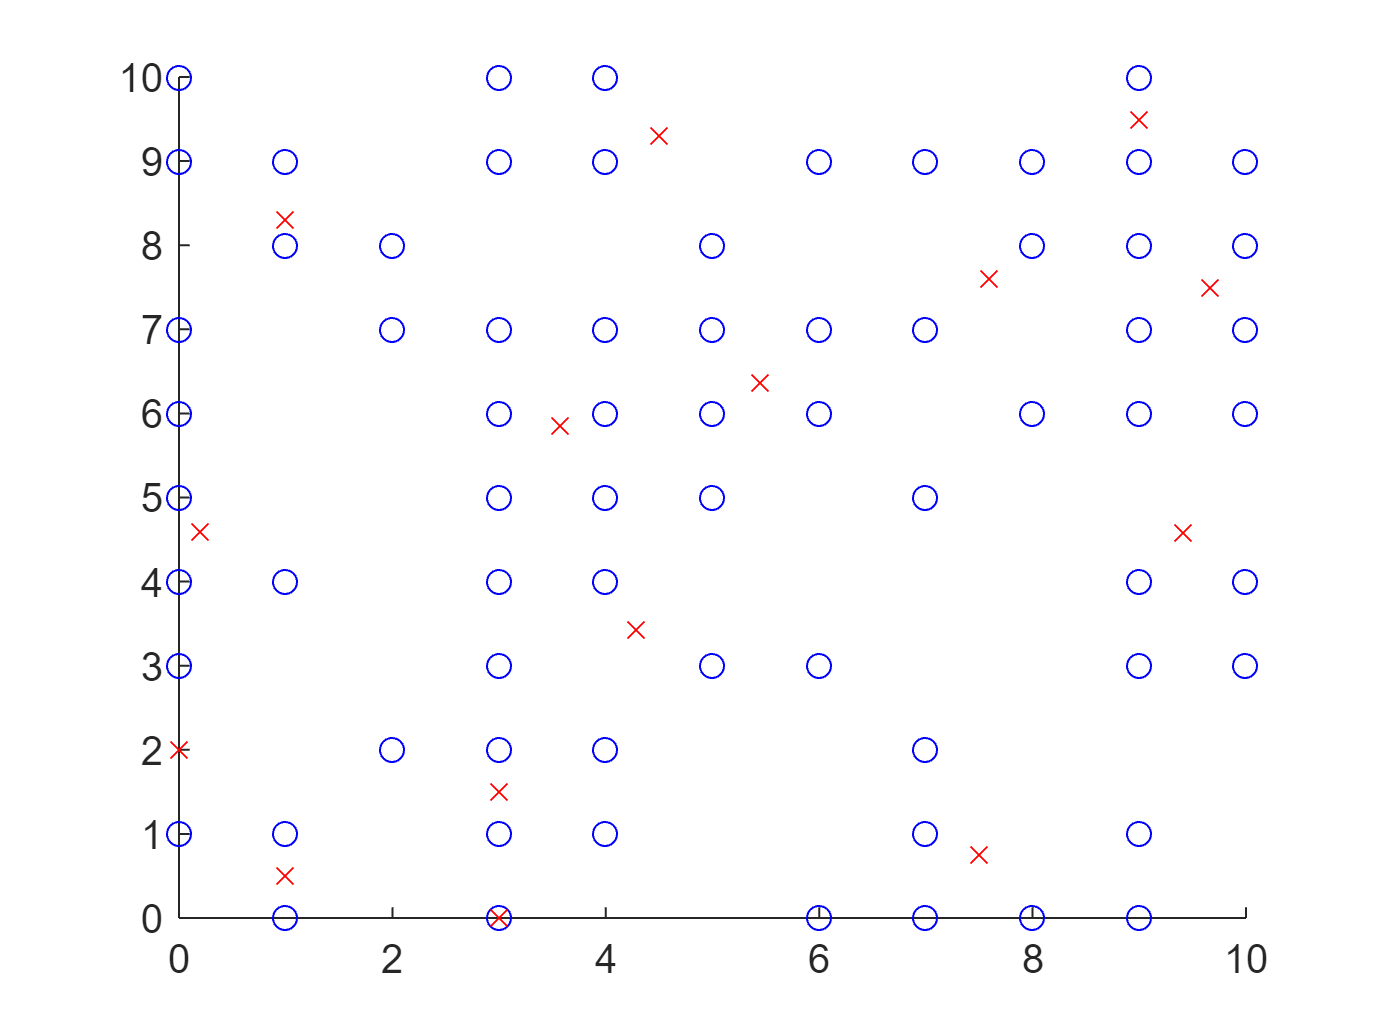

% plotting output; this is to show our algorithm works in 2D
scatter(randomPoints(1,:),randomPoints(2,:),'b','o')
hold on
scatter(startCentroids(:,1),startCentroids(:,2),'r','x')
hold off